clear all; clc;

% Robot's structure model:
%   Base 
%   q1     -Prismatic Joint
%   theta1 -virtual spring 1
%   Link1  -Rigid link
%   q2     -Rotation Joint
%   theta2 -virtual spring 2
%   Link2  -Rigid link
%   q3     -Prismatic Joint
%   Link3  -Rigid link
%   theta3 -virtual spring 3

thetas = [0 0 0];

K_theta = [1 0 0;
           0 2 0;
           0 0 0.5] * 10^6;             % stiffness of virtual springs 

K_estimated = K_theta;

links = [0.4 0.1];

num_exp = 30;

q1_range = [-pi pi];
q2_range = [0 1];
q3_range = [0 1];
force_range = [-1000 1000];

AA = 0;
Adt = 0;

for exp = 1:num_exp
    q1 = q1_range(1) + 2*q1_range(2)*rand(1);
    q2 = q2_range(1) + 2*q2_range(2)*rand(1);
    q3 = q3_range(1) + 2*q3_range(2)*rand(1);
    W = force_range(1) + 2*force_range(2)*rand(1,6);
    
    q = [q1 q2 q3];
    
    J_theta = JacTheta(q, thetas, links);
    delta_t = (J_theta * inv(K_theta) * J_theta' * W') + randn ;
    
    J_theta = J_theta(1:3,:);
    W = W(1:3);
    delta_t = delta_t(1:3);
    
    for j = 1:size(J_theta,2)
        A(:,j) = J_theta(:,j) * J_theta(:,j)' * W' ;
    end
    
    AA = AA + A' * A;                  % 1st term = summation(A' * A)
    Adt= Adt+ A' * delta_t;            % 2nd term = sumation (A' * delta_t)
end

ks = AA \ Adt ;
Kc = 1 ./ ks ;                         % stiffness of the elastostatic model of the robot 

% Update the K_theta 
K_theta = diag(Kc);




### Designing the testing trajectory and loading:

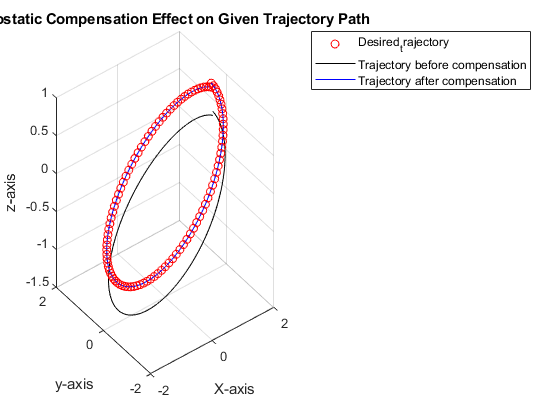

% Wrench vector (load on the end-effector)
Force = [-500, -1000, -700, 0, 0, 0];

% Desired trajectory:
% r = 0.1;
% xc = 1.1;
% yc = 0;
% zc = 2.3;

points = 100; % trajectory sampling points

radius = 1.5;
index = 0;
angle = linspace(0,2*pi,points);
for t = linspace(1,8*pi*radius,points)
    
    index = index + 1;
    z_points(index) = sin(0.5*(t+90)/pi);
    x_points(index) = radius*cos(angle(index));
    y_points(index) = radius*sin(angle(index));
end

% alpha = linspace(0, 2*pi, points);
% x_points = xc + r*cos(alpha);
% y_points = yc + r*sin(alpha);
% z_points = zc*ones(1, points);
Desired_trajectory = [x_points; y_points; z_points];

error = normrnd( 0 , 1e-5 );

for i = 1:points
    end_effector_position  = [x_points(i), y_points(i), z_points(i)];
    qs = IK(end_effector_position, links); % get ideal joint state values
    Jac = JacTheta(qs, thetas, links); % compute jacobian for the current configuration
    dt = (Jac * inv(K_theta) * Jac' * Force') + error; % find the deflection at the end-effector
    trajectory_without_compensation(:,i) = Desired_trajectory(:,i) + dt(1:3); % find the actual reached trajectory
%     trajectory_without_compensation = trajectorDesired[:, i] + dt[0:3]
    
    refined_trajectory = Desired_trajectory(:,i) - dt(1:3); % modify the trajectory to compensate for the deflection
    refined_end_effector_position  = [refined_trajectory(1), refined_trajectory(2), refined_trajectory(3)];
    refined_qs = IK(end_effector_position, links); % get joint state values
    Jac = JacTheta(refined_qs, thetas, links); % compute jacobian for the current configuration
    dt = (Jac * inv(K_theta) * Jac' * Force') + error; % find the deflection at the end-effector
    trajectory_with_compensation(:,i) = refined_trajectory + dt(1:3); % find the actual reached trajectory 
end

Desired_trajectory = Desired_trajectory(1:3,:);
trajectory_without_compensation = trajectory_without_compensation(1:3,:);
trajectory_with_compensation = trajectory_with_compensation(1:3,:);

plot3(Desired_trajectory(1,:), Desired_trajectory(2,:), Desired_trajectory(3,:), 'or')
hold on
plot3(trajectory_without_compensation(1,:), trajectory_without_compensation(2,:), trajectory_without_compensation(3,:), '-k')
hold on
plot3(trajectory_with_compensation(1,:), trajectory_with_compensation(2,:), trajectory_with_compensation(3,:), 'b')
grid on
legend('Desired_trajectory', 'Trajectory before compensation', 'Trajectory after compensation')
xlabel("X-axis")
ylabel("y-axis")
zlabel("z-axis")
title("Elastostatic Compensation Effect on Given Trajectory Path")